# Wavelet散乱変換を用いた特徴抽出とLSTMによる異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

以下のページではWavelet散乱変換を用いた特徴抽出とLSTMによる異音判定の例題が示されています。

[https://jp.mathworks.com/help/wavelet/ug/spoken-digit-recognition-with-wavelet-scattering-and-deep-learning.html](https://jp.mathworks.com/help/wavelet/ug/spoken-digit-recognition-with-wavelet-scattering-and-deep-learning.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Deep Learning Toolbox™

- Wavelet Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
downloadFolder = fullfile(tempdir,'aircompressordataset');
datasetLocation = tempdir;

if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
    loc = websave(downloadFolder,url);
    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
end

ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads); %* データのシャッフル
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

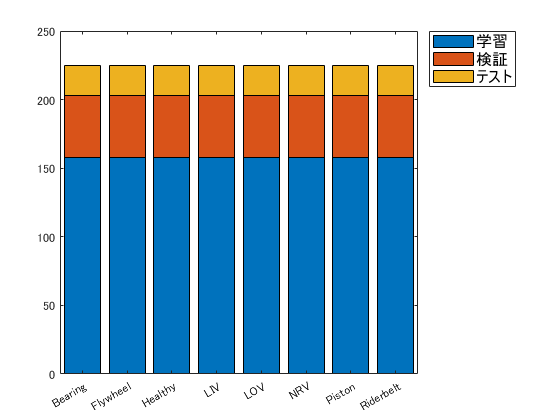

uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## データの可視化

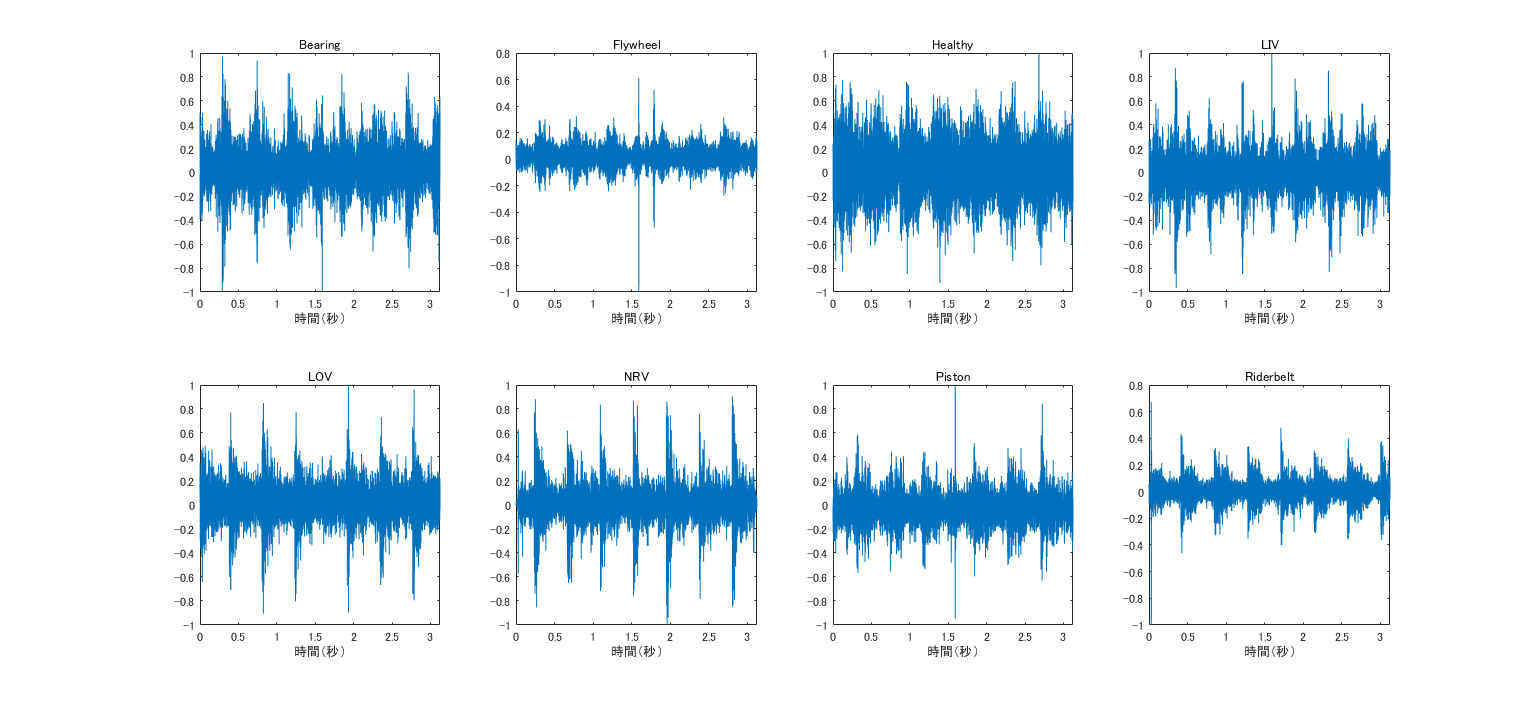

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## Wavelet散乱変換の設定

s = read(adsTrain);
reset(adsTrain);

e = (nextpow2(numel(s))-1);
N = 2^e;
batchsize = 64;

useGPU = false; % Set to true to use the GPU

sn = waveletScattering('SignalLength',N,'SamplingFrequency',16*10^3,...
    'InvarianceScale',0.5);

## 学習用データの作成

scTrain = [];

tic
while hasdata(adsTrain)
    sc = helperbatchscatfeatures(adsTrain,sn,N,batchsize,useGPU);
    scTrain = cat(3,scTrain,sc);
end
toc

経過時間は 27.688429 秒です。


## 検証用データの作成

scValidation = [];

tic
while hasdata(adsValidation)
   sc = helperbatchscatfeatures(adsValidation,sn,N,batchsize,useGPU);
   scValidation = cat(3,scValidation,sc); 
end
toc

経過時間は 7.418973 秒です。


## テスト用データの作成

scTest = [];

tic
while hasdata(adsTest)
   sc = helperbatchscatfeatures(adsTest,sn,N,batchsize,useGPU);
   scTest = cat(3,scTest,sc); 
end
toc

経過時間は 3.426814 秒です。


## ネットワークへの入力サイズの調整

TrainFeatures = scTrain(2:end,:,:)

TrainFeatures = 329×3×1264 の single 配列
TrainFeatures(:,:,1) =
  -10.2034  -13.0508  -13.0543
  -10.1850  -13.0262  -13.0825
  -10.1557  -13.0995  -13.0750
  -10.1185  -13.1510  -13.1325
  -10.0771  -13.1913  -13.1522
   -9.9770  -12.7575  -12.7582
   -9.4300  -10.6510  -10.6574
   -8.0894   -8.5979   -8.4882
   -6.6563   -7.3010   -7.2207
   -6.5973   -7.1668   -7.0804
   -7.7777   -8.3349   -8.3109
   -7.1296   -7.5875   -7.4737
   -6.0797   -6.5608   -6.3358
   -5.4157   -5.7320   -5.5555
   -4.8247   -5.1899   -4.8951
   -4.4782   -4.7801   -4.5039
   -4.1688   -4.4471   -4.3510
   -3.9890   -4.4533   -4.2686
   -4.1680   -4.5806   -4.5276
   -4.0515   -4.6432   -4.3578
   -3.9149   -4.2994   -4.1574
   -3.8052   -4.1841   -3.9440
   -3.4955   -3.8222   -3.9550
   -3.2880   -3.6336   -3.3740
   -3.6303   -4.0109   -3.4856
   -3.9128   -4.1904   -3.7910
   -3.2532   -3.6244   -3.3584
   -3.2452   -3.6151   -3.2277
   -3.8346   -4.0168   -3.8221
   -3.7401   -4.0090   -4.0690
   -3.94

TrainFeatures = squeeze(num2cell(TrainFeatures,[1 2]))

TrainFeatures = 1264×1 の cell 配列
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}
    {329×3 single}

YTrain = adsTrain.Labels;

ValidationFeatures = scValidation(2:end,:,:);
ValidationFeatures = squeeze(num2cell(ValidationFeatures,[1 2]));
YValidation = adsValidation.Labels;

TestFeatures = scTest(2:end,:,:);
TestFeatures = squeeze(num2cell(TestFeatures,[1 2]));
YTest = adsTest.Labels;

## ネットワークの構築

[inputSize, ~] = size(TrainFeatures{1});

numHiddenUnits = 512;
numClasses = numel(unique(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last') %* LSTM
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## 学習のオプション

maxEpochs = 100;
miniBatchSize = 128;
validationFrequency = floor(numel(YTrain)/miniBatchSize); % 検証頻度

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0001,...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','shortest', ...
    'Shuffle','every-epoch',...
    'Verbose', false, ...
    'Plots','training-progress',...
    'ValidationData',{ValidationFeatures,YValidation},...
    'ValidationFrequency',validationFrequency);

## 学習の開始

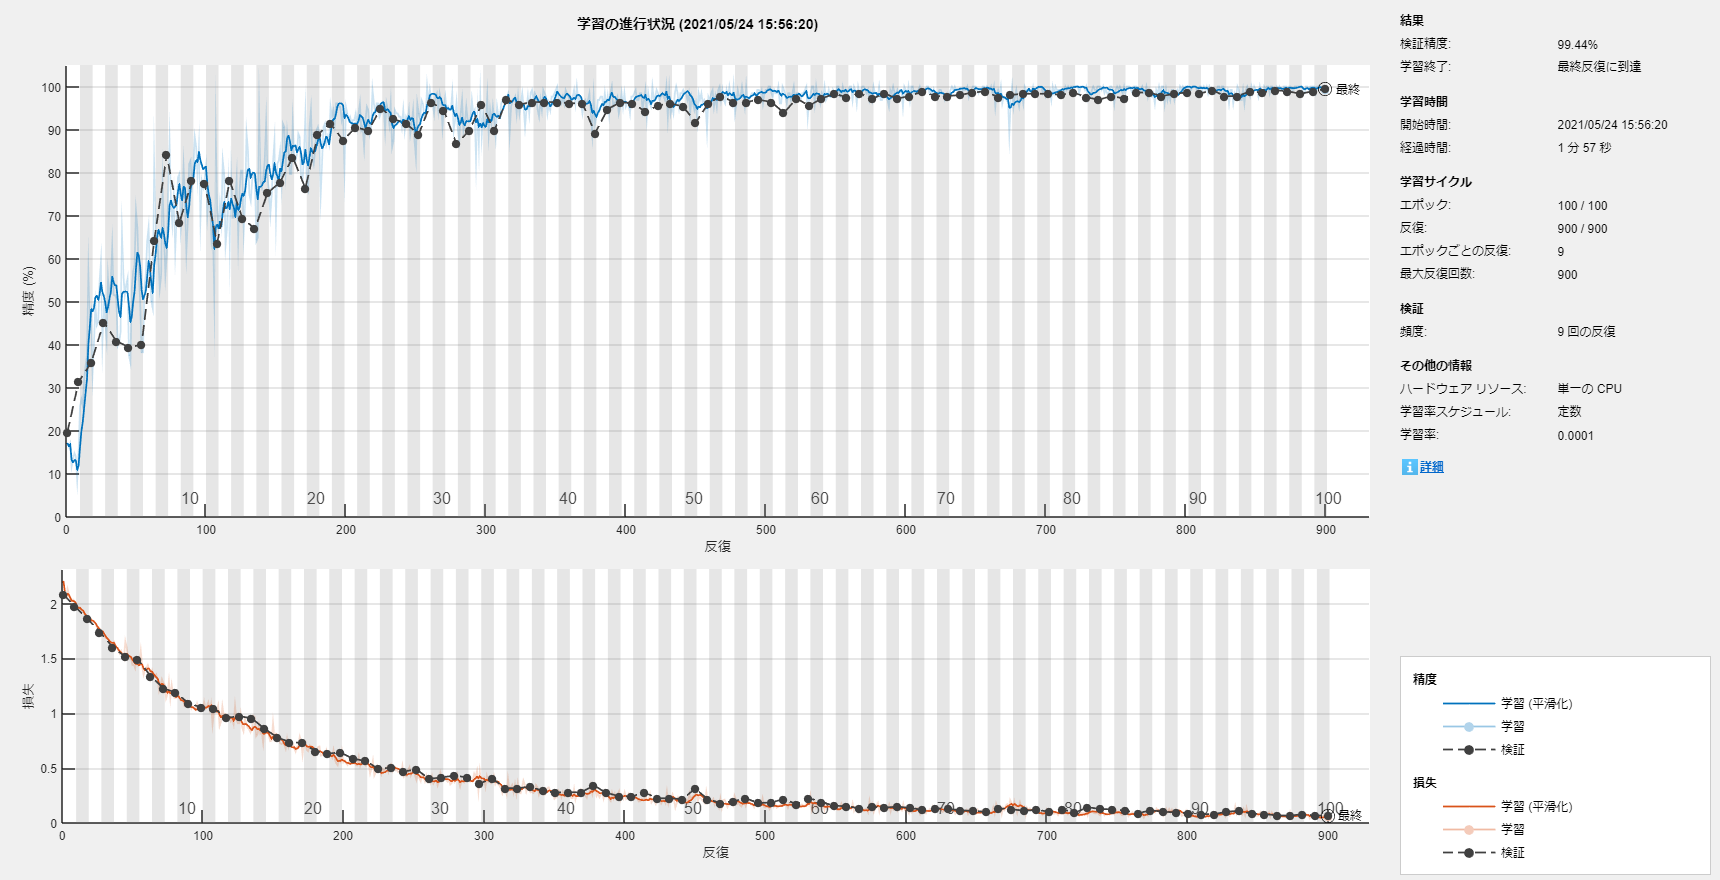

net = trainNetwork(TrainFeatures,YTrain,layers,options);

## テスト：精度検証

tblTest

tblTest = 8×2 table
      Label      Count
    _________    _____
    Bearing       22  
    Flywheel      22  
    Healthy       22  
    LIV           22  
    LOV           22  
    NRV           22  
    Piston        22  
    Riderbelt     22  

YPred = classify(net,TestFeatures);
accuracy = 100*sum(YPred == YTest) / numel(YTest) % 精度（%）

accuracy = 98.8636

## 混同行列

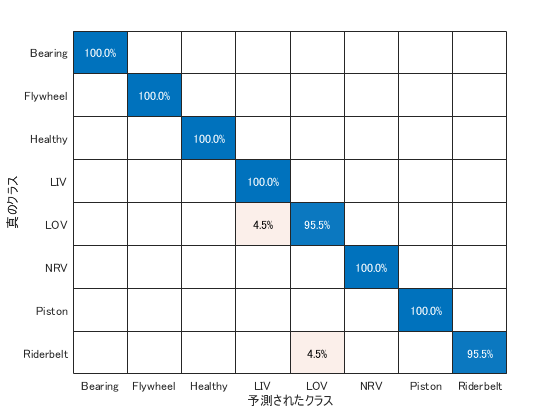

figure; clf;
confusionchart(YTest, YPred,"Normalization","row-normalized")

## 精度の可視化

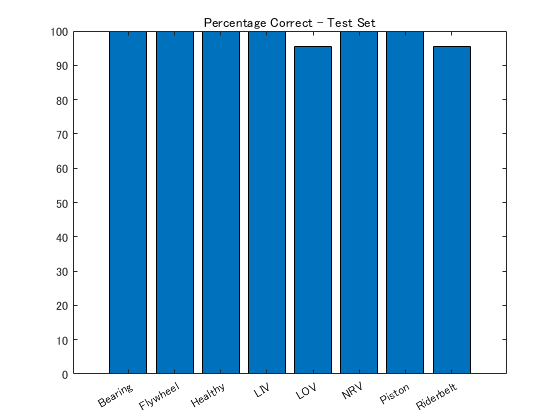

cm = confusionmat(YTest, YPred);
genreAccuracy = diag(cm)./tblTest.Count*100;
figure; clf;
bar(genreAccuracy)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct - Test Set');

**helperbatchscatfeatures** - This function returns the wavelet time scattering feature matrix for a given input signal. In this case, we use the natural logarithm of the wavelet scattering coefficients. The scattering feature matrix is computed on $2^{19}$ samples of a signal. The scattering features are subsampled by a factor of 6. If `useGPU` is set to `true`, the scattering transform is computed on the GPU.

function sc = helperbatchscatfeatures(ds,sn,N,batchsize,useGPU)
% This function is only intended to support examples in the Wavelet
% Toolbox. It may be changed or removed in a future release.

% Read batch of data from audio datastore
batch = helperReadBatch(ds,N,batchsize);
if useGPU
    batch = gpuArray(batch);
end

% Obtain scattering features
S = sn.featureMatrix(batch,'transform','log');
gather(batch);
S = gather(S);
    
% Subsample the features
sc = S(:,1:6:end,:);
end

**helperReadBatch** - This function reads batches of a specified size from a datastore and returns the output in single precision. Each column of the output is a separate signal from the datastore. The output may have fewer columns than the batchsize if the datastore does not have enough records.

function batchout = helperReadBatch(ds,N,batchsize)
% This function is only in support of Wavelet Toolbox examples. It may
% change or be removed in a future release.
%
% batchout = readReadBatch(ds,N,batchsize) where ds is the Datastore and
%   ds is the Datastore
%   batchsize is the batchsize

kk = 1;

while(hasdata(ds)) && kk <= batchsize
    tmpRead = read(ds);
    batchout(:,kk) = cast(tmpRead(1:N),'single'); %#ok<AGROW>
    kk = kk+1;
end

end